predictor1 = [3794287 1773567 2313540 1674434 2088814 2242848 3088142 ];
timenc1 = [2.133 1.142 1.405 1.566 1.845 1.591 1.506 ];
timedec1 = [0.476 0.146 0.467 0.164 0.551 0.405 0.240 ];

predictor2 = [ 3649594 1755248 2197381 1490854 1859110 1690828 3038707 ];
timenc2 = [ 2.312 1.325 1.516 1.154 1.812 1.631 1.566 ];
timedec2 = [ 0.258 0.344 0.158 0.249 0.160 0.373 0.569];

predictor3 = [ 3752782 1827276 2218309 1434644 1851475 1616527 3095103 ];
timenc3 = [ 2.033 1.163 1.743 1.296 1.304 1.182 1.659 ];
timedec3 = [ 0.411 0.871 0.589 0.432 0.576 0.684 0.237 ];

predictor4 = [ 4375182 2146598 2832965 2068982 2741106 3209742 3585396];
timenc4 = [ 2.322 1.164 1.547 1.224 1.525 1.966 1.716 ];
timedec4 = [ 0.935 0.863 0.834 0.132 0.228 0.501 0.316 ];

flac = [3453480 1630879 1982826 1343156 1703000 1419483 2753911];

frames = [1294188 647388 882588 588588 911988 1058988 941388];
samples = frames .* 2;
predictor1 = predictor1 .* 8 ./ samples;
predictor2 = predictor2 .* 8 ./ samples;
predictor3 = predictor3 .* 8 ./ samples;
predictor4 = predictor4 .* 8 ./ samples;
flac = flac .* 8 ./ samples;

res = (sum(timenc1) + sum(timenc2) + sum(timenc3) + sum(timenc4)) / (sum(length(timenc1)) + sum(length(timenc2)) + sum(length(timenc3)) + sum(length(timenc4)))

res = 1.5839

res = (sum(timedec1) + sum(timedec2) + sum(timedec3) + sum(timedec4)) / (sum(length(timedec1)) + sum(length(timedec2)) + sum(length(timedec3)) + sum(length(timedec4)))

res = 0.4346

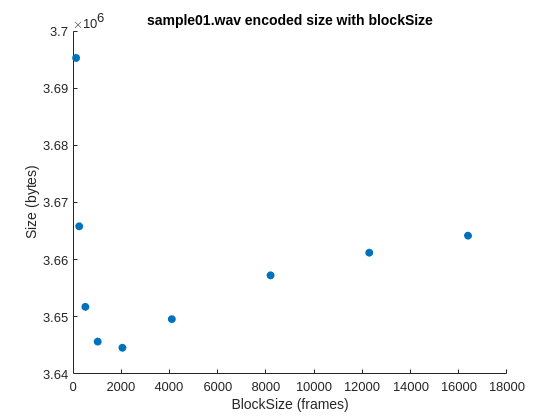


blocksize = [128 256 512 1024 2048 4096 8192 12288 16384];
sample01b = [3695292 3665840 3651748 3645666 3644585 3649594 3657257 3661221 3664200];
sample06b = [1975009 1838490 1742598 1678082 1637536 1616527 1605481 1604909 1603294];

scatter(blocksize, sample01b, "filled");
title('sample01.wav encoded size with blockSize');
xlabel('BlockSize (frames)');
ylabel('Size (bytes)');

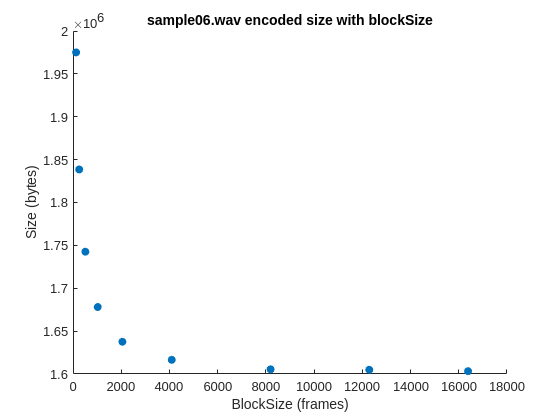


scatter(blocksize, sample06b, "filled");
title('sample06.wav encoded size with blockSize');
xlabel('BlockSize (frames)');
ylabel('Size (bytes)');

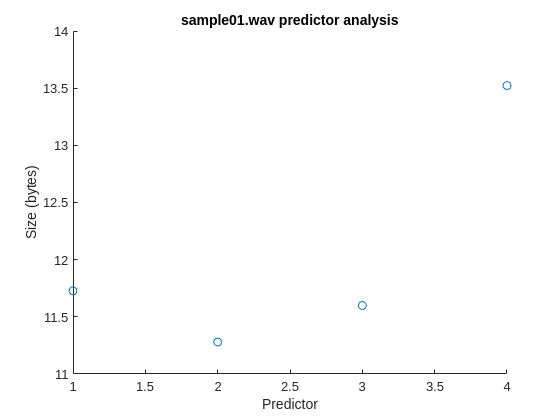


s = 1;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample01.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');

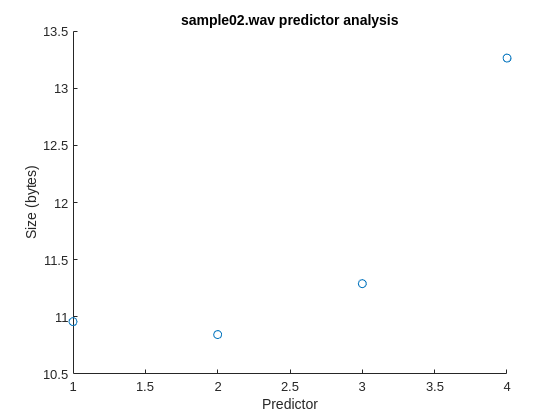


s = 2;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample02.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');

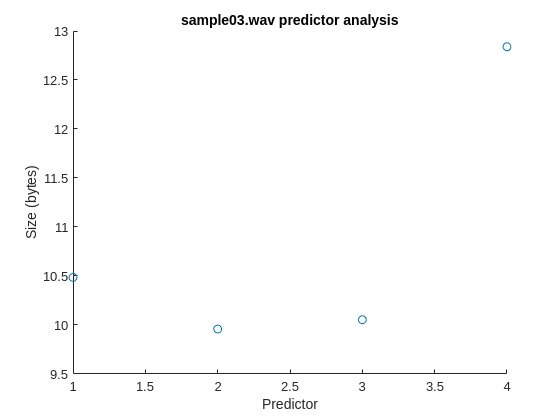


s = 3;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample03.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');

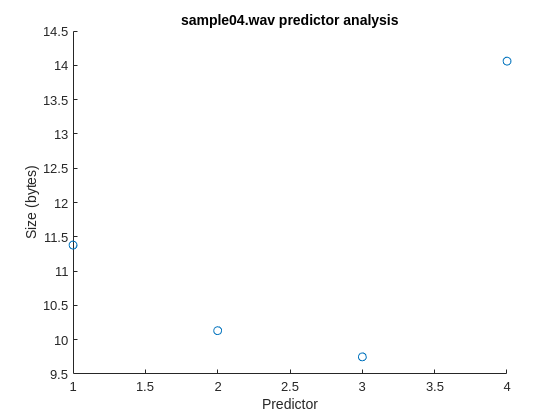


s = 4;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample04.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');

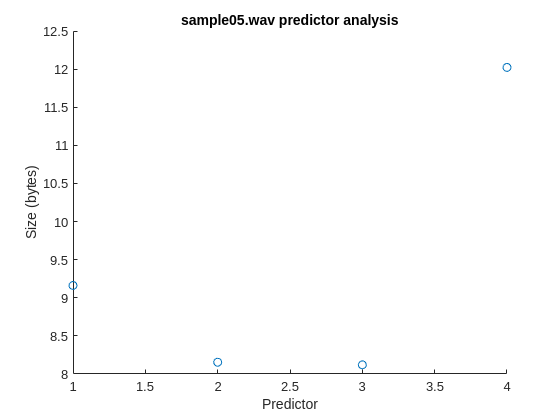


s = 5;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample05.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');

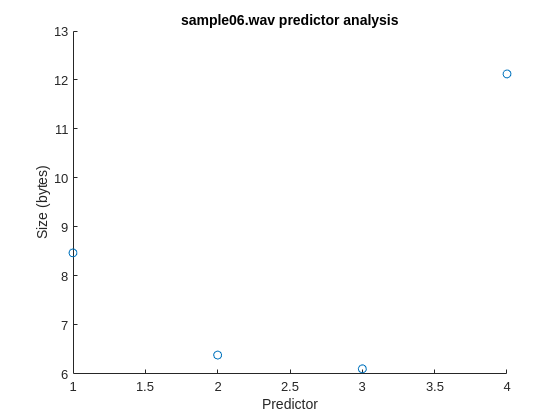


s = 6;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample06.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');

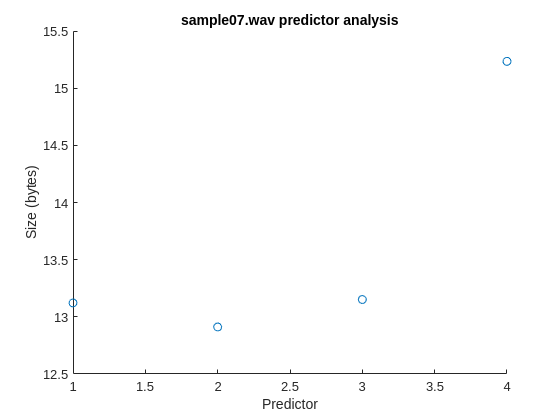


s = 7;
scatter([1 2 3 4], [predictor1(s) predictor2(s) predictor3(s) predictor4(s)]);
title('sample07.wav predictor analysis');
xlabel('Predictor');
ylabel('Size (bytes)');